# 1.1

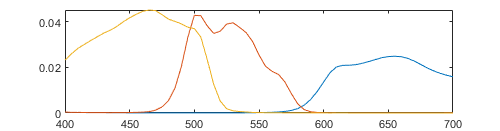

n = length(Ad);
x = linspace(400,700,n);
plot(x,Ad)

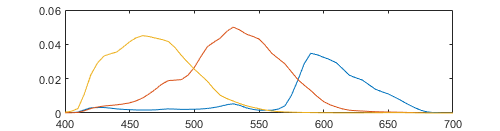

plot(x,Ad2)

Ad & Ad2 looks similar but not exact. They will definitly give different outputs. We think Ad2 will give a higher contrast image.

Answer: No.

# 1.2

## Camera 1

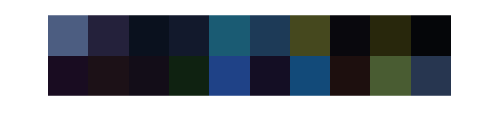

e = CIED65 .* chips20;

% raw (i.e. un-calibrated) camera output for the 20 surfaces
d = Ad'*e';

showRGB(d')

## Camera 2

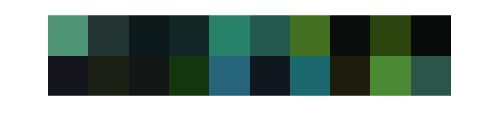

% raw (i.e. un-calibrated) camera output for the 20 surfaces
d = Ad2'*e';

showRGB(d')

# 2.1

ref1 = Ad'*CIED65';
ref2 = Ad2'*CIED65';

cf1 = ones(3,1) ./ ref1

cf1 =     2.4579
    1.6735
    1.0250


cf2 = ones(3,1) ./ ref2

cf2 =     2.2382
    1.0786
    1.1449


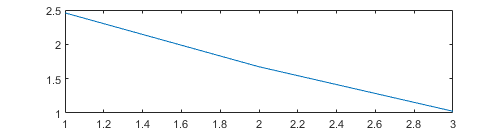


plot(cf1)

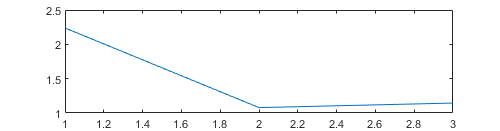

plot(cf2)

# 2.2

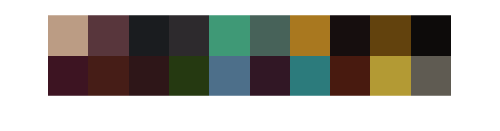

e = CIED65 .* chips20;

RAW_C1_CIED65 = Ad'*e';
RAW_C2_CIED65 = Ad2'*e';

CAL_DATA_C1_CIED65 = RAW_C1_CIED65 .* cf1;
CAL_DATA_C2_CIED65 = RAW_C2_CIED65 .* cf2;
 
showRGB(CAL_DATA_C1_CIED65')

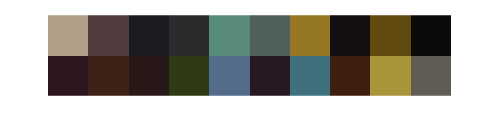

showRGB(CAL_DATA_C2_CIED65')

# 2.3

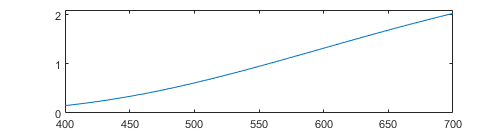

n = length(CIEA);
x = linspace(400,700,n);
plot(x,CIEA)
ylim([0,2.1])

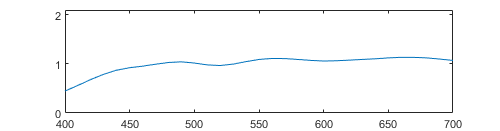

plot(x,CIEB)
ylim([0,2.1])

# 2.4

e = CIED65 .* chips20;
e2 = CIEA .* chips20;

% 1 Taking a picture of 20 surfaces
d1_raw_65 = Ad'*e';
d1_raw_CIEA = Ad'*e2';

% 2 Taking a picture of a completely white surface (ones)
d1_raw_65_v = Ad'*CIED65';
d1_raw_CIEA_v = Ad'*CIEA';

% 3 Calibration factors, same!
cf1 = ones(3,1) ./ d1_raw_65_v;
cf2 = ones(3,1) ./ d1_raw_CIEA_v;

% 1 multiplied with calibration factors
RGB_cal_CIE65 = d1_raw_65 .* cf1;
RGB_cal_CIEA = d1_raw_CIEA .* cf2;

showRGB(d1_raw_65')

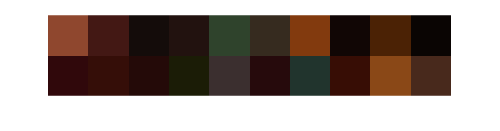

showRGB(d1_raw_CIEA')


showRGB(RGB_cal_CIE65')

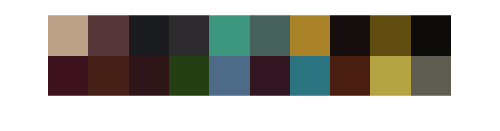

showRGB(RGB_cal_CIEA')

# 2.5

% d = Ad' * (chips20 .* CIEA)'
e = CIED65 .* chips20;
e2 = CIEA .* chips20;

% 1 Taking a picture of 20 surfaces
d1_raw_65 = Ad'*e';
d1_raw_CIEA = Ad'*e2';

ref1 = Ad'*CIED65';
ref2 = Ad'*CIEA';

cf = ones(3,1) ./ ref1;
cf2 = ones(3,1) ./ ref2;

RGB_cal_D65 = d1_raw_65 .* cf;
RGB_cal_A = d1_raw_CIEA .* cf2;

showRGB(RGB_cal_D65')

showRGB(RGB_cal_A')

# 3.1

% d = Ad' * (chips20 .* CIEA)'
% Facit
k = 100 ./ (CIED65 * xyz(:,2))

k = 4.6460


xyzValuesFromSpectra = xyz'*( CIED65 .* chips20 )' * k

xyzValuesFromSpectra =    66.5076   29.1415   10.3354   17.0944   37.2524   31.4696   51.8681    7.1516   35.7168    4.5704   14.7977   21.2515   13.6952   19.1563   34.5574   13.8335   26.8255   20.8937   59.1042   36.1553
   67.2653   25.9561   10.4588   16.8158   49.3000   35.3276   57.1830    6.4429   38.2742    4.5382   10.4425   18.0936   11.4180   25.1057   36.1143   10.5687   34.9493   17.7770   67.6801   37.2942
   61.0087   28.3929   14.4753   20.9340   50.2915   40.5003   10.0020    6.4265    5.4609    4.4085   16.5167   10.6582   11.4388    7.5209   65.7332   18.0017   54.8397    6.5922   17.7720   37.8082


# 3.2

CAL_DATA_C1_CIED65_XYZ = M_XYZ2RGB \ CAL_DATA_C1_CIED65

CAL_DATA_C1_CIED65_XYZ =    61.4216   26.0837   10.2211   16.2227   39.8786   31.5440   46.4218    6.3725   25.9743    4.1970   15.0404   16.9131   12.2893   15.0703   37.7502   13.7985   33.1094   16.3093   54.2934   33.8779
   63.0462   24.2983   10.8037   16.6752   51.3648   35.8823   48.7659    5.9971   27.0307    4.2841   11.6314   14.4964   10.7275   19.4173   41.3933   11.5790   41.7006   13.6408   59.6931   35.7370
   57.9539   25.7464   13.0108   18.9900   51.3964   38.3589   18.3944    5.9291    8.5139    4.1745   13.9536   10.4942   10.4511    9.3090   57.3145   15.1818   52.1366    7.2105   27.8020   35.4879


C_XYZ = CAL_DATA_C1_CIED65_XYZ

C_XYZ =    61.4216   26.0837   10.2211   16.2227   39.8786   31.5440   46.4218    6.3725   25.9743    4.1970   15.0404   16.9131   12.2893   15.0703   37.7502   13.7985   33.1094   16.3093   54.2934   33.8779
   63.0462   24.2983   10.8037   16.6752   51.3648   35.8823   48.7659    5.9971   27.0307    4.2841   11.6314   14.4964   10.7275   19.4173   41.3933   11.5790   41.7006   13.6408   59.6931   35.7370
   57.9539   25.7464   13.0108   18.9900   51.3964   38.3589   18.3944    5.9291    8.5139    4.1745   13.9536   10.4942   10.4511    9.3090   57.3145   15.1818   52.1366    7.2105   27.8020   35.4879


REF_XYZ = xyzValuesFromSpectra

REF_XYZ =    66.5076   29.1415   10.3354   17.0944   37.2524   31.4696   51.8681    7.1516   35.7168    4.5704   14.7977   21.2515   13.6952   19.1563   34.5574   13.8335   26.8255   20.8937   59.1042   36.1553
   67.2653   25.9561   10.4588   16.8158   49.3000   35.3276   57.1830    6.4429   38.2742    4.5382   10.4425   18.0936   11.4180   25.1057   36.1143   10.5687   34.9493   17.7770   67.6801   37.2942
   61.0087   28.3929   14.4753   20.9340   50.2915   40.5003   10.0020    6.4265    5.4609    4.4085   16.5167   10.6582   11.4388    7.5209   65.7332   18.0017   54.8397    6.5922   17.7720   37.8082



[L, a, b] =  xyz2lab(C_XYZ(1,:)', C_XYZ(2,:)', C_XYZ(3,:)');

C_LAB = zeros(3,20);
C_LAB(1,:) = L;
C_LAB(2,:) = a;
C_LAB(3,:) = b;

[L, a, b] =  xyz2lab(REF_XYZ(1,:)', REF_XYZ(2,:)', REF_XYZ(3,:)');

REF_LAB = zeros(3,20);
REF_LAB(1,:) = L;
REF_LAB(2,:) = a;
REF_LAB(3,:) = b;

dE = euclidean_distance_lab(REF_LAB, C_LAB)

dE =     3.2156    5.5486    5.6898    5.2263    3.3262    3.6343   29.5862    3.3362   29.1100    1.8346   11.7746    9.1123    4.4273   17.6858   15.6904   11.7195   12.3890   13.0436   25.4438    2.9847



mean(dE)

ans = 10.7389

max(dE)

ans = 29.5862

# 3.3

plot(x, Ad)

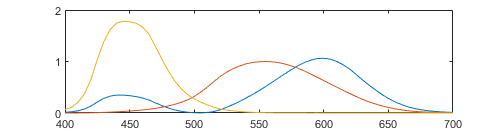

plot(x, xyz)

# 3.4

D = CAL_DATA_C1_CIED65'

D =     0.7323    0.6115    0.5183
    0.3434    0.2137    0.2372
    0.1003    0.1090    0.1212
    0.1747    0.1635    0.1758
    0.2465    0.5984    0.4608
    0.2794    0.3833    0.3499
    0.6630    0.4725    0.1208
    0.0848    0.0532    0.0540
    0.3837    0.2589    0.0493
    0.0493    0.0414    0.0377


C = xyzValuesFromSpectra'

C =    66.5076   67.2653   61.0087
   29.1415   25.9561   28.3929
   10.3354   10.4588   14.4753
   17.0944   16.8158   20.9340
   37.2524   49.3000   50.2915
   31.4696   35.3276   40.5003
   51.8681   57.1830   10.0020
    7.1516    6.4429    6.4265
   35.7168   38.2742    5.4609
    4.5704    4.5382    4.4085


A = pinv(D)*C

A =    57.8087   35.4363    4.3470
   32.8479   80.8301  -17.5626
    5.8561  -17.6682  131.0000



xyz_aprox = D * A

xyz_aprox =    65.4559   66.2204   60.3402
   28.2594   25.2527   28.8067
   10.0878   10.2237   14.3996
   16.4985   16.2988   20.9164
   36.6042   48.9640   50.9269
   30.7919   34.7039   40.3202
   54.5556   59.5546   10.4098
    6.9636    6.3498    6.5079
   30.9761   33.6520    3.5824
    4.4338    4.4301    4.4298



dE = euclidean_distance_lab(xyz_aprox', C')

dE =     1.6263    1.2017    0.3498    0.7892    0.9678    0.9385    3.6075    0.2250    6.8824    0.1755    3.1403    1.6296    0.4889    4.9682    1.0323    1.5282    2.6055    1.1569    3.8487    1.4936


mean(dE)

ans = 1.9328

max(dE)

ans = 6.8824

# 3.5

D = CAL_DATA_C1_CIED65'

D =     0.7323    0.6115    0.5183
    0.3434    0.2137    0.2372
    0.1003    0.1090    0.1212
    0.1747    0.1635    0.1758
    0.2465    0.5984    0.4608
    0.2794    0.3833    0.3499
    0.6630    0.4725    0.1208
    0.0848    0.0532    0.0540
    0.3837    0.2589    0.0493
    0.0493    0.0414    0.0377


C = xyzValuesFromSpectra'

C =    66.5076   67.2653   61.0087
   29.1415   25.9561   28.3929
   10.3354   10.4588   14.4753
   17.0944   16.8158   20.9340
   37.2524   49.3000   50.2915
   31.4696   35.3276   40.5003
   51.8681   57.1830   10.0020
    7.1516    6.4429    6.4265
   35.7168   38.2742    5.4609
    4.5704    4.5382    4.4085


A11 = Optimize_poly(D', C')

A11 =    -0.7995   -0.8977   -0.3789
   75.1263   49.8895    5.3527
   64.0013  113.8726    2.5622
  -30.1857  -50.7934  116.5608
  -57.3227  -48.1319  -12.0854
   34.9241   20.3505   -9.8759
    6.3861    7.5254   15.8510
  -63.1461  -51.9633   -1.1304
   47.3285   19.8588  -57.1795
   -7.0608    4.6118   37.0742


xyz_aprox_a11 = Polynomial_regression(D', A11)

xyz_aprox_a11 =    66.5096   27.8573    9.7750   16.6392   36.9511   32.1922   52.3149    7.0672   34.8667    4.3226   15.8613   20.8865   14.1754   19.8283   34.5017   13.8445   26.9130   21.3759   58.9062   36.5895
   67.2542   24.9010    9.9852   16.4765   49.0317   35.9394   57.5626    6.3649   37.3760    4.2559   11.2072   17.8821   11.9189   25.7486   36.1026   10.4850   35.0129   18.3282   67.5508   37.6216
   60.9787   28.5960   14.3552   20.9662   50.1102   40.5785    9.8074    6.3964    5.0991    4.3336   16.2770   10.9571   11.5759    7.7201   65.7413   17.6776   55.0127    6.9452   18.0166   37.6376



dE = euclidean_distance_lab(xyz_aprox_a11, C')

dE =     0.0321    1.6744    0.7435    0.5687    0.4423    0.9500    0.6178    0.1188    1.2885    0.3830    1.3317    0.5170    0.7073    0.9511    0.0575    0.3349    0.2039    0.8130    0.3402    0.5699


mean(dE)

ans = 0.6323

max(dE)

ans = 1.6744

# # Functions

function dE = euclidean_distance_lab(V1, V2)
    arguments
        V1 (3,20) {mustBeNumeric, mustBeNumeric}
        V2 (3,20) {mustBeNumeric, mustBeNumeric}
    end
    L1 = V1(1,:);
    L2 = V2(1,:);

    a1 = V1(2,:);
    a2 = V2(2,:);

    b1 = V1(3,:);
    b2 = V2(3,:);

    dE = sqrt((L1-L2).^2 + (a1-a2).^2 + (b1-b2).^2);
end